# Matched Filter Probability of Detection

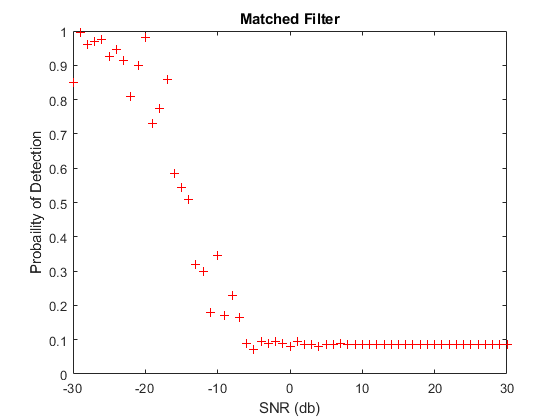

clear
mySNR = -30:30;
find_PD_MF(50,mySNR)

function find_PD_MF(threshold,snr)
    waveform = phased.LinearFMWaveform('PulseWidth',1e-4,'PRF',5e3,...
                'SampleRate',1e6,'OutputFormat','Pulses','NumPulses',1,...
                'SweepBandwidth',1e5);
            
    wav = getMatchedFilter(waveform);
    
    inputSignal = waveform();
    
    taylorfilter = phased.MatchedFilter('Coefficients',wav,...
                   'SpectrumWindow','Taylor');
               
    N= length(inputSignal);
    
    for i = 1:length(snr)
        filtredSignal_taylor = abs(taylorfilter(awgn(inputSignal,snr(i))));
        highValue = filtredSignal_taylor > threshold;
        PD = sum(highValue)/N;
        plot(snr(i),PD,'r+');
        hold on
        title('Matched Filter')
        xlabel('SNR (db)')
        ylabel('Probaility of Detection')
    end
    hold off
end
